## MATLAB Code for Sketching the Low-Frequency Conductance of an Ideal Diode

### Constants

I0 = 1e-12;  % Reverse saturation current (A)
m = 2;       % Ideality factor (for demonstration, usually between 1 and 2)
Vt = 25.9e-3;  % Thermal voltage at room temperature (V)
V = linspace(-0.7, 0.7, 200);  % Voltage from -0.7V to 0.7V


### Diode current equation

I = I0 * (exp(V / (m * Vt)) - 1);


### Conductance G = dI/dV

#### For simplicity, approximate dI/dV using finite difference

G = diff(I) ./ diff(V);


### Plotting

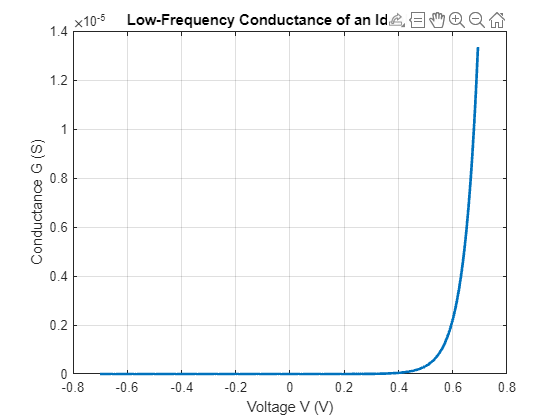

figure;
plot(V(1:end-1), G, 'LineWidth', 2);
xlabel('Voltage V (V)');
ylabel('Conductance G (S)');
title('Low-Frequency Conductance of an Ideal Diode');
grid on;